%主成分分析（第一套方法）
clear all;      %清理内存    
%数据标准化并计算相关系数
% load C:\MATLAB7\work\cities2003             
cities2003 %调出保存的数据
data=[data(:,1),data(:,2),data(:,3),365-data(:,4)];
mv=mean(data);                               %计算各变量的均值
st=std(data);                                %计算各变量的标准差
[n,m]=size(data);                            %计算矩阵的函数和列数
X=(data-mv(ones(n,1),:))./st(ones(n,1),:);   %原始数据集体标准化
X

X =     0.7132    0.1655    2.1000    1.2636
    0.4644    0.5579    0.7178    0.4678
    1.7705    2.9123    0.1650    1.5222
    1.6772    1.3125   -0.7334    2.1190
   -0.0642   -0.4985    0.3032    0.0302
    0.5266   -0.1061   -0.3879   -0.2086
   -0.6239   -1.3135   -1.3554   -1.0839
    0.0913   -0.3778    1.6163   -0.1887
   -0.6550   -0.3778    1.0634   -0.7457
    0.0602   -0.7702    0.5105   -0.1887


%基于标准化数据计算相关系数的三种方法
R=X'*X/(n-1);                                %计算相关系数矩阵
R=cov(X);                                    %计算相关系数矩阵
R=corrcoef(X);                               %计算相关系数矩阵
R

R =     1.0000    0.7239    0.3930    0.9094
    0.7239    1.0000    0.2784    0.6351
    0.3930    0.2784    1.0000    0.3707
    0.9094    0.6351    0.3707    1.0000



%主成分分析的完整计算过程
[U,V]=eig(R);                                %计算特征向量和特征值矩阵
E=transpose(rot90(U));                       %将特征向量矩阵P旋转90度再转置
G=rot90(rot90(V));                           %将对角矩阵旋转180度
eigv=diag(G);                                %提取角矩阵的对角线元素
per=100*eigv/sum(eigv);                      %计算方差贡献百分比
Cum=cumsum(per);                             %计算方差贡献累计百分比
C=sqrtm(G);                                  %将对角矩阵对角线元素化为平方根
A=-E*C;                                      %计算载荷矩阵(转换为负值)
Co1=A(:,1).^2;                               %提取1个主成分的公因子方差
Co2=Co1+A(:,2).^2;                           %提取2个主成分的公因子方差
Co3=Co2+A(:,3).^2;                           %提取3个主成分的公因子方差
Co4=Co3+A(:,4).^2;                           %提取4个主成分的公因子方差
Comm=[Co1,Co2,Co3,Co4];                      %将4个公因子方差向量合并为一个矩阵
H=A(:,1:2);                                  %提取第一、第二主成分的载荷
Z=X*(-E);                                    %计算主成分得分(转换为负值)
stdr=std(Z);                                 %计算主成分得分的标准差
F=Z./stdr(ones(n,1),:);                      %主成分得分集体标准化
f=F(:,1:2);                                  %提取第一、第二主成分的标准化得分
E,G,Cum,Co2,H,f                              %输出常用结果

E =     0.5763    0.1519    0.2693    0.7565
    0.4987    0.2816   -0.8060   -0.1495
    0.3304   -0.9361   -0.1186   -0.0216
    0.5568    0.1461    0.5135   -0.6363


G =     2.7302         0         0         0
         0    0.7946         0         0
         0         0    0.3944         0
         0         0         0    0.0807


Cum =    68.2556
   88.1205
   97.9816
  100.0000


Co2 =     0.9252
    0.7419
    0.9944
    0.8633


H =    -0.9523   -0.1354
   -0.8240   -0.2510
   -0.5460    0.8344
   -0.9200   -0.1303


f =    -1.1445    1.8243
   -0.6316    0.4218
   -2.0423   -1.2979
   -1.5484   -1.8181
    0.1020    0.4819
   -0.0038   -0.4294
    1.2503   -0.7245
   -0.1775    1.8320
    0.3811    1.4699
    0.1729    0.8001


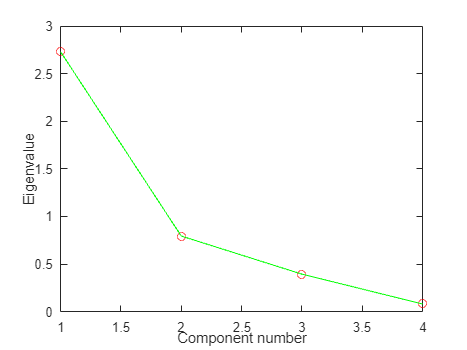


%一些图形的绘制
%特征值分布的折线图
figure(1);                                   %创造第一个图形窗口
plot(eigv,'rO');                             %绘制特征值的散点图
xlabel('Component number');                  %横轴标签(成分数)
ylabel('Eigenvalue');                        %纵轴标签（特征值）
hold on                                      %保持图形
plot(eigv,'g-');                             %将特征值的散点连接起来
hold off                                     %第一次绘图结束

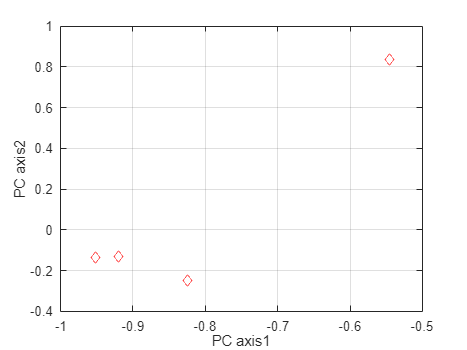

%主成分载荷图
figure(2);                                   %创造第二个图形窗口
a1=A(:,1);a2=A(:,2);                         %提取载荷矩阵中的向量
plot(a1,a2,'rd');                            %绘制主成分载荷图
xlabel('PC axis1');                          %横轴标签(主轴1)
ylabel('PC axis2');                          %纵轴标签(主轴2)
grid on                                      %添加网格

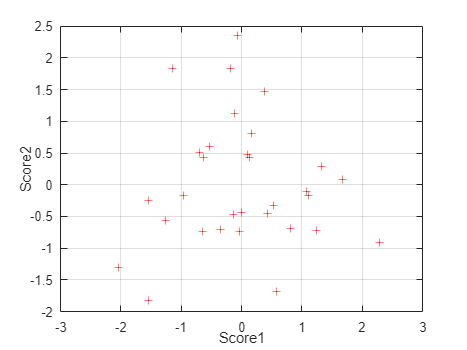

%主成分得分图
figure(3);                                   %创造第三个图形窗口
f1=F(:,1);f2=F(:,2);                         %提取得分矩阵中的向量
plot(f1,f2,'r+');                            %绘制主成分得分图
xlabel('Score1');                            %横轴标签(第一主成分)
ylabel('Score2');                            %纵轴标签(第二主成分)
grid on                                      %添加网格

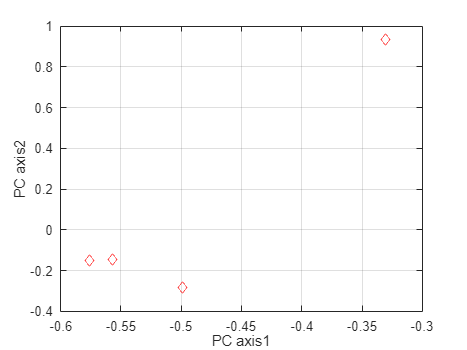


%计算T平方统计量(1)
L=F.^2;                                      %标准化主成分数值取平方
T=L(:,1)+L(:,2)+L(:,3)+L(:,4);               %计算T统计量

%特征向量图(效果等价于主成分载荷图)
figure(4);                                   %创造第二个图形窗口
e1=-E(:,1);e2=-E(:,2);                       %提取特征向量并转换符号
plot(e1,e2,'rd');                            %绘制特征向量图
xlabel('PC axis1');                          %横轴标签(主轴1)
ylabel('PC axis2');                          %纵轴标签(主轴2)
grid on                                      %添加网格


%几个用于检验的语句
%计算再生相关系数矩阵
Rp=H*H';                                     %计算再生相关矩阵
Re=R-Rp;                                     %计算相关矩阵的残差矩阵
%计算非标准化数据协方差矩阵的三种方法
Covz=Z'*Z/(n-1);                             %计算协方差矩阵
Covz=cov(Z);                                 %计算协方差矩阵
%计算主成分得分相关系数的四种方法
Rz=F'*F/(n-1);                               %计算相关系数矩阵
Rz=cov(F);                                   %计算协方差矩阵
Rz=corrcoef(F);                              %计算相关系数矩阵
Rz=corrcoef(Z);                              %计算相关系数矩阵

%综合得分

S=Z(:,1)+Z(:,2)+Z(:,3)+Z(:,4)                %非标准化得分四列加和

S =    -0.3889
   -0.4529
   -3.3549
   -4.4879
    0.2338
   -1.1106
    0.4820
    1.0884
    2.3083
    0.2496


S1=F(:,1)*eigv(1)^0.5+F(:,2)*eigv(2)^0.5+F(:,3)*eigv(3)^0.5+F(:,4)*eigv(4)^0.5

S1 =    -0.3889
   -0.4529
   -3.3549
   -4.4879
    0.2338
   -1.1106
    0.4820
    1.0884
    2.3083
    0.2496



%计算T平方统计量(2)
for i=1:n
    T=sumsqr(F(i,:));
end

%数据重构
data=[data(:,1),data(:,2),data(:,3),365-data(:,4)];